## 1方向のラドン変換を完成させよう．

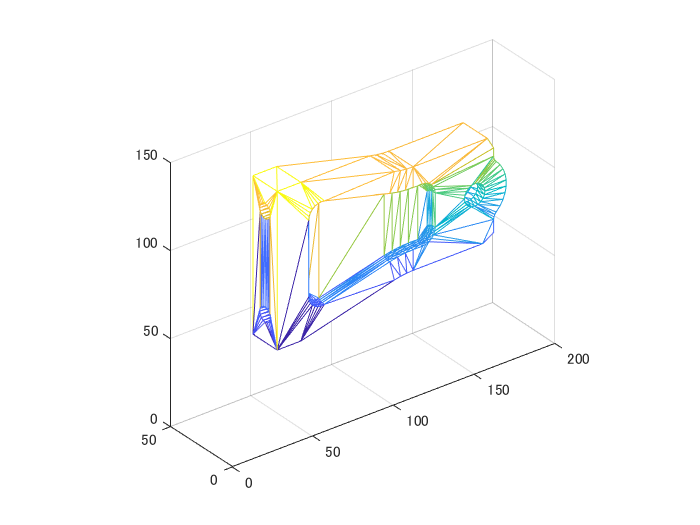

### 課題：上図のモデルの体積を配列volumeとして求めてください．volume の仕様は以下の通りです．

            volume の大きさは 1 $\times $ 200 です．

- volume(1) には x=1 から x=2 の区間における体積を保管します．

- volume(2) には x=2 から x=3 の区間における体積を保管します．

- 
$$\vdots$$


- volume(k) には x=k から x=k+1 の区間における体積を保管します．

- 
$$\vdots$$


- volume(200) には x=200 から x=201 の区間における体積を保管します．

#### 以下のコードを完成させてください．

clear;

TR = stlread('sampleModel.stl');

p = TR.Points;
c = TR.ConnectivityList;


volume = zeros(1,200);

% ↓ c_idx は頂点連結リストの行番号
for c_idx = 1:height(c)
    % ↓ c_list に c_idx 行目のリストを代入
    c_list = c(c_idx, :);

    % ↓　c_list の１番目の頂点 p1 = [x, y, z]; を作成
    p1 = p(c_list(1),:);
    % ↓ c_list の２番目の頂点 p2 = [x, y, z]; を作成
    p2 = p(c_list(2),:);
    % ↓ c_list の３番目の頂点 p3 = [x, y, z]; を作成
    p3 = p(c_list(3),:);

    % 外積 (パッチの表の方向に垂直に伸びる法線ベクトル)　を計算
    normal = cross(p2 - p1, p3 - p1);

    pos_neg = 1;
    if normal(3) > 0 % ← 法線ベクトルが上向きのとき
        % 正の体積
        pos_neg = 1;
    elseif normal(3) < 0 % ← 法線ベクトルが下向きのとき
        % 負の体積
        pos_neg = -1;
    else % ← 法線ベクトルの z が 0 のとき
        continue; % ← continue は continue 以降の処理を飛ばすして次のループに入るという意味．
    end

    P = [
        p1;
        p2;
        p3
        ];

    %%%%%%%%%%%%% ↓ sortrows() の括弧内を正しく書き換えましょう．%%%%%%%%%%%%%
    P_sorted_by_x = sortrows();
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    p_xmin = P_sorted_by_x(1,:);
    p_xmid = P_sorted_by_x(2,:);
    p_xmax = P_sorted_by_x(3,:);

    % p_xmin から p_xmid までの区間における体積を計算しましょう．

    old_volume = 0; % 1つ前 (old) の体積
    current_volume = 0; % 現在 (current) の体積

    %%%%%%%%%%%%%%　↓　正しく書きましょう %%%%%%%%%%%%%%%%%%%
    for slice_X = p_xmin(1)+1:p_xmid(1)
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        %%%%%%% ↓ 正しく書きましょう %%%%%%%%%%%%%%%%%%%%%%%%%%%%
        current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
        volume(1) = volume(1) + pos_neg*(current_volume - old_volume); % ← volume のインデクスを正しく書き換えてください．
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        old_volume = current_volume;
    end

    %%%%%%%　↓　p_xmid 付近の計算をしましょう．　%%%%%%%%%

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



    % p_xmax から p_xmid までの区間における体積を計算しましょう．

    old_volume = 0; % 1つ前 (old) の体積
    current_volume = 0; % 現在 (current) の体積


    % for 文を降順 100, 99, 98, ..., 1 とするには for slice_X = 100:-1:1
    % :-1: は差分がマイナス１という意味．

    %%%%%%%%%%%%%%　↓　正しく書きましょう %%%%%%%%%%%%%%%%%%
    for slice_X = p_xmax(1):-1:p_xmid(1)
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        %%%%%%%%%%%%%%　↓　正しく書きましょう %%%%%%%%%%%%%%%%%%
        current_volume = 0; % ← calc_volume(), slice_edge(), p_xmin, p_xmid, p_xmax, slice_X を使って書き換えてください．
        volume(1) = volume(1) + pos_neg*(current_volume - old_volume); % ← volume のインデクスを正しく書き換えてください．
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        old_volume = current_volume;
    end

    %%%%%%%　↓　p_xmid付近の計算をしましょう．　%%%%%%%%

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
end